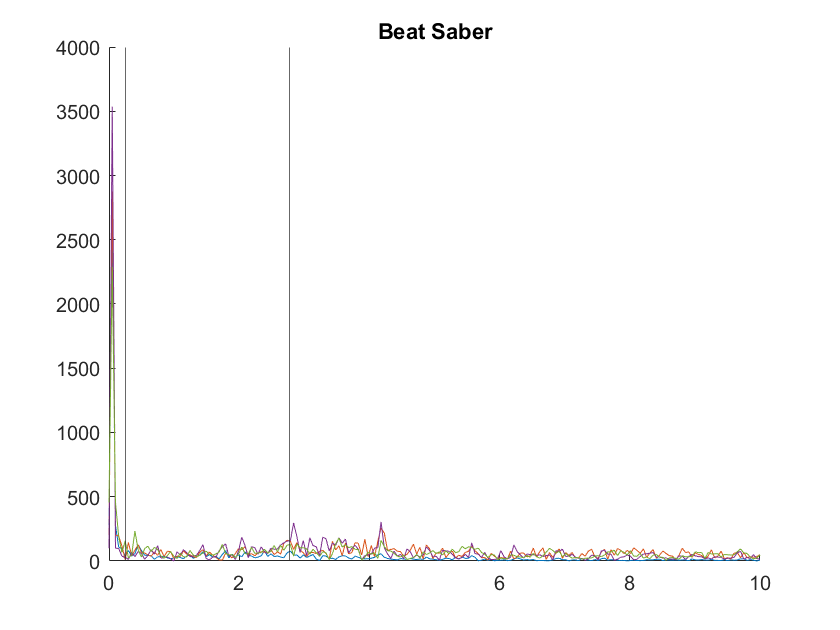

[data_train, data_test, flag_train, flag_test, shuffled] = get_data(20, 25);
xdata = 10 * (0:length(data_train) - 1) / (length(data_train) - 1);

figure(1);
clf;
hold on
for i = 1:5
    plot(xdata, abs(data_train(:, i)))
end
xline(166 / 60)
title("Beat Saber");

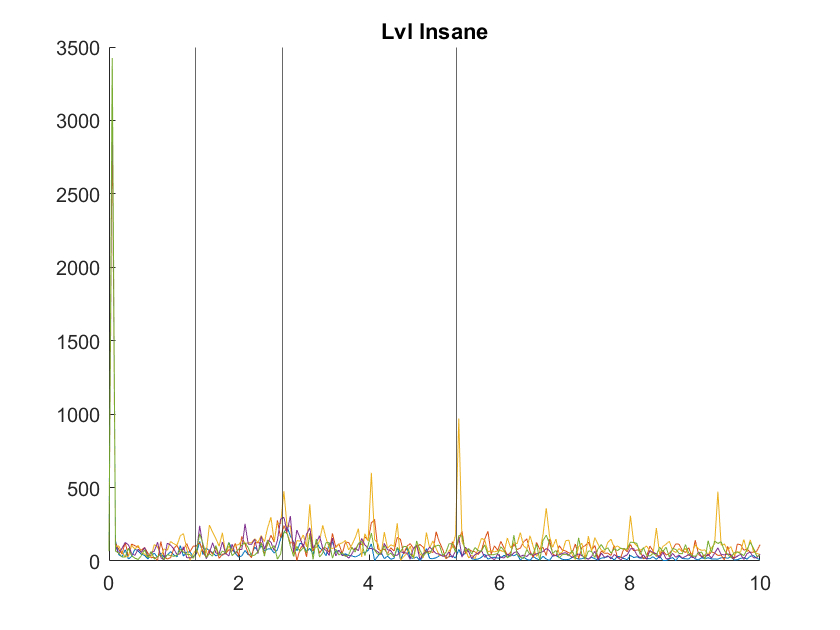


figure(2);
clf;
hold on
for i = 21:25
    plot(xdata, abs(data_train(:, i)))
end
xline(160 / 60)
xline(80 / 60)
xline(320 / 60)
title("Lvl Insane")

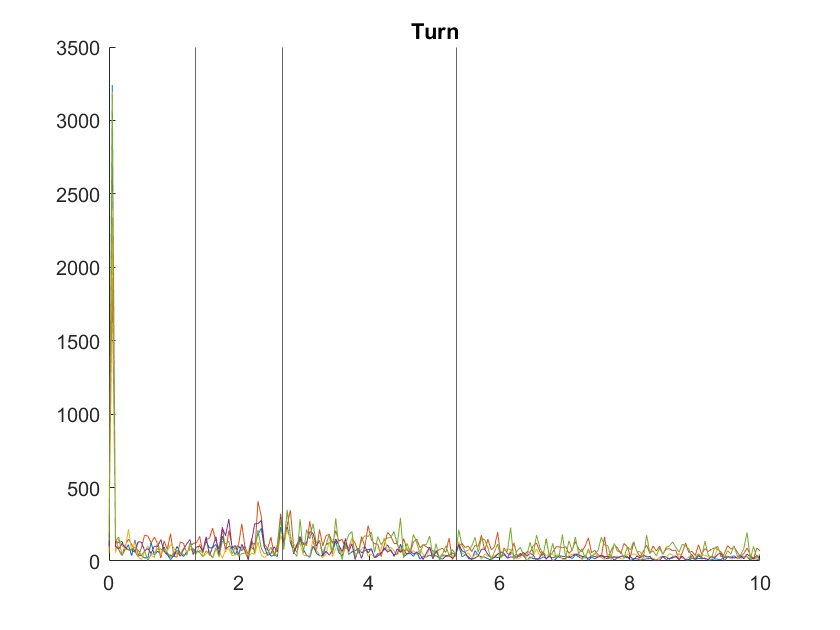



figure(3)
clf;
hold on
for i = 41:45
    plot(xdata, abs(data_train(:, i)))
end
xline(160 / 60)
xline(80 / 60)
xline(320 / 60)
title("Turn")

% Load the data
[data_train, data_test, flag_train, flag_test, shuffled] = get_data(20, 25);

% Take the magnitude so we don't deal with complex regression
data_train = abs(data_train);
data_test = abs(data_test);

% Get the indexes of the answers
[M, Iflagtest] = max(flag_test');
[M, Iflagtrain] = max(flag_train');

% Train the weight matrix
w = (data_train*data_train')\(data_train*flag_train);


% Grade of the training data
a_train = transpose(data_train)*w;
[M, Itrain] = max(a_train');
train_accuracy = mean(Itrain == Iflagtrain)

% Grade of the testing data
a_test = transpose(data_test)*w;
[M, Itest] = max(a_test');
test_accuracy = mean(Itest == Iflagtest)

av = 0.4000

ans = 1182×1 datetime array
   04-Dec-2021 11:17:53.427
   04-Dec-2021 11:17:53.527
   04-Dec-2021 11:17:53.626
   04-Dec-2021 11:17:53.726
   04-Dec-2021 11:17:53.826
   04-Dec-2021 11:17:53.926
   04-Dec-2021 11:17:54.026
   04-Dec-2021 11:17:54.126
   04-Dec-2021 11:17:54.226
   04-Dec-2021 11:17:54.325
   04-Dec-2021 11:17:54.425
   04-Dec-2021 11:17:54.525
   04-Dec-2021 11:17:54.625
   04-Dec-2021 11:17:54.725
   04-Dec-2021 11:17:54.825
   04-Dec-2021 11:17:54.925
   04-Dec-2021 11:17:55.024
   04-Dec-2021 11:17:55.124
   04-Dec-2021 11:17:55.224
   04-Dec-2021 11:17:55.324
   04-Dec-2021 11:17:55.424
   04-Dec-2021 11:17:55.524
   04-Dec-2021 11:17:55.624
   04-Dec-2021 11:17:55.724
   04-Dec-2021 11:17:55.823
   04-Dec-2021 11:17:55.923
   04-Dec-2021 11:17:56.023
   04-Dec-2021 11:17:56.123
   04-Dec-2021 11:17:56.223
   04-Dec-2021 11:17:56.323
